% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0)
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp
settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;

# Optimization-based Robot Control

## Introduction

In the last lesson, you learned the concept of task-space singularities and a particular way to address them. 

In this lesson, we will revisit the topic of robot control using quadratic optimiziation formalism.

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

## Notation

Keep these in mind (we will also use this notation when writting papers to conferences and journals):

- ${\it \bf h} \in\mathbb{H}$: a quaternion. (Bold-face, lowercase character)

- $\underline{{\it \bf h}}\in\mathcal{H}$: a dual quaternion. (Bold-face, underlined, lowercase character)

- ${\it \bf{p}},{\it \bf{t}},\cdots\in \mathbb{H}_p$: pure quaternions. They represent points, positions, and translations. They are quaternions for which $\text{Re}\left({\it \bf h}\right)=0$.

- ${\it \bf r}\in\mathbb{S}^3$: unit quaternions. They represent orientations and rotations. They are quaternions for which $||{\it \bf h}||=1$. 

- $\underline{\it \bf x} \in$$\underline{\mathcal{S}}$: unit dual quaternions. They represent poses and pose transformations. They are dual quaternions for which $||{\it \bf h}||=1$.

- $\underline{{\it \bf l}}\in \mathcal{H}_p\cap$$\underline{\bf{\mathcal{S}}}$: a Plücker line. 

- $\underline{{\it \bf \pi}}\in \left\{ P\left(\underline{{\it \bf \pi}}\right) \in \mathbb{H}_p\right\}\cap\underline{\bf{\mathcal{S}}}$: a plane.

- $\theta,a,b,\cdots\in\mathbb{R}$: real numbers. 

- ${\it \bf q,\cdots}\in\mathbb{R}^n:$real vectors.

- ${\it \bf J}, {\it \bf A}, {\it \bf B}, \cdots \in \mathbb{R}^{m\times n}:$ real matrices.

## Robot definition

The concepts of this lesson apply to any manipulator robot. However, to have a more concrete understanding using DQ Robotics, consider the same robot as used in the past lesson.

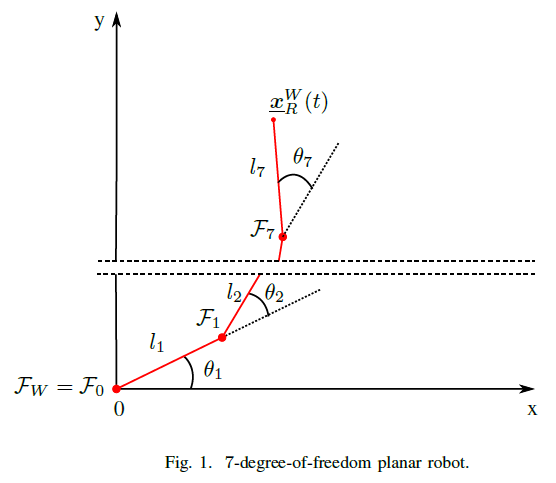

- Let the robot $R$ be a 7-DoF planar robot, as drawn in Fig.1. 

- Let $\mathcal{F}_W$ be the world-reference frame. 

- Let $\underline{\it \bf{x}}_R^W(t)\triangleq\underline{\it \bf{x}}_R$ $\in$$\underline{\mathcal{S}}$ represent the pose of the *end effector*. 

- Let $R$ be composed of seven rotational joints that rotate about their z-axis, composed in the joint-space vector ${\it \bf q}\left(t\right)\triangleq{\it \bf q}=\left[\theta_{1}\ \theta_{2}\ \theta_{3}\ \theta_{4}\ \theta_{5}\ \theta_{6}\ \theta_{7}\right]^{T}$ with $\theta_{i}\left(t\right)\triangleq\theta_{i}\in\mathbb{R}$ for $i=1,2,\ldots,7$. The rotation of the reference frames of each joint coincide with the rotation of $\mathcal{F}_W$ when $\theta_{i}=0$. The length of the joints are $l_i \in$$\mathbb{R}^+-\{0\}$.

- Consider that we can freely control the joint vector ${\it \bf q}$.

This robot can be modeled by the following class.

Let us instantiate our robot as follows

seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

## A brief review of quadratic optimization

At some point in your education you might have been introduced to optimization problems. There are many types of optimization problems and in this lesson we will address only two types, which are enough to solve a large class of robot control problems.

### Unconstrained quadratic optimization

The first type is called unconstrained quadratic optimization of type


$$\min_{\dot{\it \bf q}}\  \mathcal{F}\left(q\right)$$


where $\mathcal{F}\left(q\right)\in\mathbb{R}^+$ is a quadratic *objective function* that depends on the current joint configuration. Note that it is called an *optimization problem*, and **NOT** an equation (note that there is no equality sign). In mathematical optimization terminology, $\dot{\it \bf q}$ is called the *decision variable*. 

You can read that as "find the $\dot{\it \bf q}$ that minimizes $ \mathcal{F}\left(q\right)$". The solution for an unconstrained quadratic optimization problem can, in general, be found analytically. In this lesson we will call that minimizer as $\dot{\it \bf q}^o$.  

### Quadratic programming

The second type of optimization problem that we will address is called quadratic programming (QP), which is a linearly-constrained quadratic optimization problem, in the form


$$\min_{\dot{\it \bf q}}\ \ \ \ \ \ \mathcal{F}\left(q\right) \\
\text{subject to}\ {\it \bf W}\dot{\it \bf q}\preceq{\it \bf w}$$


where $ {\it \bf W}\in\mathbb{R}^{n\times p}$ and $ {\it \bf w}\in\mathbb{R}^{p}$ represent $p$ linear constraints related to the $n$ degrees-of-freedom of the robot. Note that we use $\preceq$ and not $\leq$ because we are representing element-wise inequalities. 

You can read that QP as "find $\dot{\it \bf q}$ that minimizes $ \mathcal{F}\left(q\right)$, subject to ${\it \bf W}\dot{\it \bf q}$ less or equal to ${\it \bf w}$". In general, numerical methods are required to obtain a solution for a QP. Similarly to the unconstrained case, in this lesson we will call that minimizer as $\dot{\it \bf q}^o$.  

## The damped pseudo-inverse as the solution of an unconstrained quadratic optimization problem

In the last lesson, the meaning of the damping factor was introduced in the point-of-view of the SVD of the robot's task Jacobian.

The damping factor can be trivially understood when we re-write the robot control problem in the following way


$$\min_{\dot{\it \bf q}}\  ||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2+\lambda^2|| \dot{\it \bf q}||^2$$


where ${\it \bf J}\in\mathbb{R}^{m\times n}$ is the task Jacobian for an $n-$DoF robot and an $m-$DoF task. In addition, $\eta\in\mathbb{R}^+-\{0\}$ is the proportional gain of the controller and $\tilde{\it \bf x}\in\mathbb{R}^m$ is the task error. Lastly, $\lambda \in \mathbb{R}$ is the damping factor. 

Note that we are balancing two terms in the objective function. The first term, $ ||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2$, will be high when the task error is high and zero when the task error is zero. The second term, $\lambda^2||\dot{\it \bf q}||^2$, will penalize high joint velocities depending on the size of the damping factor. As we saw in practice in the last lesson, the damping factor is used as a term to balance task error convergence and the norm of the joint velocities.

Given that we have an unconstrained quadratic optimization problem which is, by definition, convex, the solution is straightforward. The optimum is where the first-order partial derivative of the objective function with respect to the decision variable equals to zero. Hence


$$\frac{\partial}{\partial\dot{\it \bf q}}\left( ||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2\right) = 0$$



$$\frac{\partial}{\partial\dot{\it \bf q}}\left[ ({\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x})^T({\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x})\right] = 0$$



$$\frac{\partial}{\partial\dot{\it \bf q}}\left(  \dot{\it \bf q}^T{\it \bf J}^T{\it \bf J}\dot{\it \bf q} +  2 \dot{\it \bf q}^T{\it \bf J}^T\tilde{\it \bf x} + \eta^2\tilde{\it \bf x}^T\tilde{\it \bf x}+\lambda^2\dot{\it \bf q}^T\dot{\it \bf q}\right) = 0$$



$$2{\it \bf J}^T{\it \bf J}\dot{\it \bf q} +  2{\it \bf J}^T\tilde{\it \bf x} +2\lambda^2\dot{\it \bf q} = 0$$



$$\left({\it \bf J}^T{\it \bf J} +\lambda^2{\it \bf I}\right)\dot{\it \bf q} = -  {\it \bf J}^T\tilde{\it \bf x}$$



$$\therefore\dot{\it \bf q}^o\triangleq -  \left({\it \bf J}^T{\it \bf J} +\lambda^2{\it \bf I}\right)^{-1}{\it \bf J}^T\tilde{\it \bf x}$$


Notice that this solution is **exacly the same** as the damped pseudo-inverse used in the last lesson.

## Joint limits

Using unconstrained optimization to solve robot-control tasks is useful in some cases, but most tasks in practice have what we call *hard limits*. They are called that way in the sense that those limits are joint-space or task-space limits that cannot be trespassed. For instance, joint limits are a physical type of hard limit. The controller cannot command the robot to move over its joint limits.

When performing kinematic control, the decision variable are the joint velocities and not the joint positions. Therefore, we need to write the joint limits as a linear inequality that depends on the joint velocities. 

Suppose that the lower joint limits are ${\it \bf q}^-\in\mathbb{R}^n$ and the upper joint limits are ${\it \bf q}^+\in\mathbb{R}^n$. The most common way of implementing joint limits using a QP is as follows


$$\min_{\dot{\it \bf q}}\ \ \ \ \ \ \||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2+\lambda^2|| \dot{\it \bf q}||^2 \\
\text{subject to}\ {\it \bf W}_{JL}\dot{\it \bf q}\preceq{\it \bf w}_{JL}$$


where


$${\it \bf W}_{JL}=\left[\matrix{
-{\it \bf I} \cr
{\it \bf I} \cr
}\right]$$


and 


$${\it \bf w}_{JL}=\left[\matrix{
-\eta_{JL}\left({\it \bf q}^{-}-{\it \bf q}\right) \cr
\eta_{JL}\left({\it \bf q}^{+}-{\it \bf q}\right) \cr
}\right].$$


where $\eta_{JL}\in\mathbb{R}^+-\{0\}$ is a configurable gain. In general, we choose $\eta_{JL}=1$.

The main idea behind this constraint is to constrain the velocity of the joint in the direction of the joint limit. 

### DQ Robotics Example

To solve QPs as described in this lesson using DQ Robotics, use the following class

help DQ_ClassicQPController

  Abstract class that defines a control law based on quadratic programming.
 
  DQ_ClassicQPController Methods:
    compute_objective_function_symmetric_matrix - compute the matrix H used in the objective function qdot'*H*qdot + f'*qdot
    compute_objective_function_linear_component - compute the vector f used in the objective function qdot'*H*qdot + f'*qdot
 
  For more methods and properties, see also DQ_KinematicController.

    Documentation for DQ_ClassicQPController



To solve a QP, you have to choose the numerical solver that will be used by the controller. MATLAB has a solver in its optimization toolbox called "quadprog". To use it, first instantiate the robot and the solver

clear all;
close all;
include_namespace_dq;

% Define the robot
seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

% Robot definition
seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();
% Solver definition
qp_solver = DQ_QuadprogSolver();

and then instantiate the controller and set the control objective, the gain, and the damping factor

% Controller definition
translation_controller = DQ_ClassicQPController(seven_dof_planar_robot, qp_solver);
translation_controller.set_control_objective(ControlObjective.Translation);
translation_controller.set_gain(10);
translation_controller.set_damping(1);

Let us define the following joint limits

% Joint limits
q_minus = -(pi/8)*ones(7,1);
q_plus  = (pi/8)*ones(7,1);

We define the other control-related variables as in the last lesson.

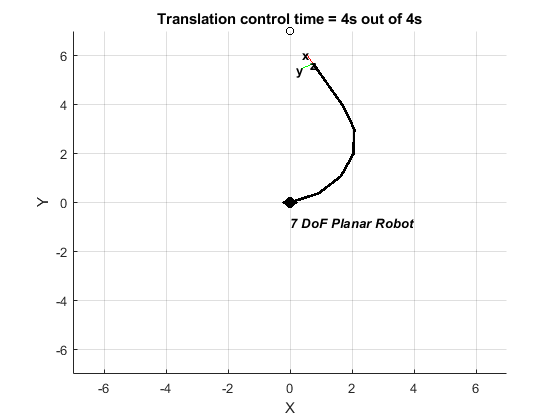

% Desired translation (pure quaternion)
td = 7*j_;
% Sampling time [s]
tau = 0.01;
% Simulation time [s]
final_time = 4;
% Initial joint values [rad]
q = zeros(7,1);
% Store the joint values
stored_q = [];

% Translation controller loop.
for time=0:tau:final_time
    

The linear inequalities depend on the current joint values so we calculate them inside the control loop.

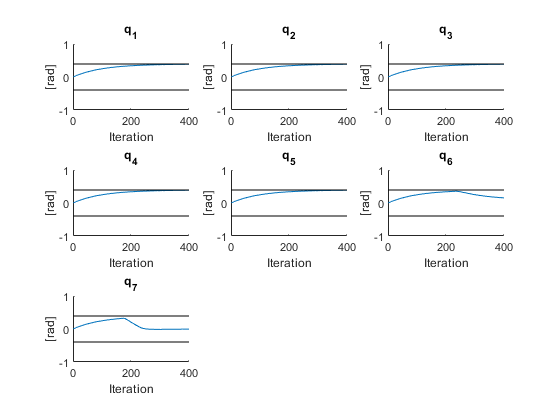

    % Define the linear inequality matrix and the linear inequality vector
    Wjl = [-eye(7); eye(7)];
    wjl = [-1*(q_minus-q); 1*(q_plus-q)];
    

We then add them to the controller using the following method

    % Update the linear inequalities in the controller
    translation_controller.set_inequality_constraint(Wjl, wjl);
    

The rest of the control loop is unchanged with respect to prior lessons.

    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
    
    % Move the robot
    q = q + u*tau;

Jlv =          0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0   -0.0000   -0.0000         0         0
         0         0         0         0         0         0         0
    0.7455   -0.1810   -0.8980   -1.2999   -1.3278   -0.9776   -0.4869
    5.6701    5.2939    4.5967    3.6811    2.6815    1.7448    0.8735
         0         0         0         0         0         0         0


    
    % Store data
    stored_q = [stored_q q];
    
    % Plot
    % Plot the robot
    plot(seven_dof_planar_robot,q);
    title(['Translation control' ' time = ' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot3(td.q(2),td.q(3),td.q(4), 'ko');
    hold off
    % [For animations only]
    drawnow limitrate % [For animations only] Ask MATLAB to draw the plot now
end
 

We can then verify that the joint limits have been kept.

for i=1:7
    subplot(3,3,i)
    plot(stored_q(i,:))
    hold on

Jpiv = 	1.0e+-16 *

         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0   -0.5551   -0.5551         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


    plot(repmat(q_minus(i),1,size(stored_q,2)),'k')
    plot(repmat(q_plus(i),1,size(stored_q,2)),'k')
    title(['q_{' num2str(i) '}'])
    ylim([-1 1])
    box off
    ylabel('[rad]')
    xlabel('Iteration')
end

Note that the robot was unable to reach the desired task-space translation due to the joint limits, as shown by the black lines representing the joint limits. This is exactly what we wanted: a controller that will get as close as possible to the target, while maintaning the robot's joint limits.

## Vector-field inequalities: task-space collision avoidance

We have just now seen how to use linear inequalities to prevent the robot from trespassing its joint limits. The joint limits are one of the few applications of joint-space constraints. In most cases, we are interested in having task-space constraints. That is, constraints that are definied at the task space. The difficulty in doing so is writting the task-space constraint as linear constraints in joint space. 

An effective way of doing so is called vector-field inequalities (VFIs), presented in detail in the following paper.

[[1]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf) Marinho, M. M; Adorno, B. V; Harada, K.;  and Mitsuishi, M. Dynamic Active Constraints for Surgical Robots using Vector Field Inequalities. *IEEE Transactions on Robotics (T-RO)*, 35(5): 1166–1185. October 2019. 

The VFIs are described in detail in [[1]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf), so to simplify the discussion for this lesson, consider the (signed) distance $d\triangleq d\left({\bf \it q}\right)\in\mathbb{R}$ to be the relation between some entity in the robot, such as a point, line, or plane, and another entity in the workspace. 

### Keeping the robot entity outside of a restricted zone

Consider the situation of keeping the robot entity outside of a restricted zone. We define the distance error in such way that the distance error is positive whenever the robot is outside of the restricted zone, zero when at the border, and negative when inside the restricted zone. The distance error is then $\tilde{d}\triangleq d-d_\text{safe}$, where $d_\text{safe}\in\mathbb{R}$ is the safe distance, that we suppose to be constant in time in this lesson. 

To obtain the general formulation of the VFIs, we start with the following task-space inequality, that will keep our robot outside of a restricted zone


$$\tilde{\dot{d}}\geq-\eta_d\tilde{{d}},$$


where  $\eta_d\in\mathbb{R}^+-\{0\}$ is a proportional gain. To be used in our QP, we need to re-write this as a joint-space linear constraint, which is what the VFI method does.

The VFIs are then given by


$$\tilde{\dot{d}}=\dot{d}-\dot{d}_\text{safe}=\dot{d}\geq-\eta_d\tilde{{d}}.$$


Given that the safe distance is constant in time. Now, notice that if the distance depends on the joint values, we can find a distace Jacobian such that the following holds


$$\dot{d}={\bf \it J}_d{\dot{\it \bf q}},$$


where ${\bf \it J}_d\in\mathbb{R}^{1\times n}$ is the distance Jacobian for that specific pair of entities. 

The linear constraint for that pair of entities, with respect to the joint velocities, then becomes


$${\bf \it J}_d{\dot{\it \bf q}}\geq-\eta_d\tilde{{d}}.$$


That constraint can be re-written to be compatible with our QP definition as


$$-{\bf \it J}_d{\dot{\it \bf q}}\leq\eta_d\tilde{{d}}.$$


### Keeping the robot entity inside of a safe zone

The reasoning is basically the same of the restricted zone case, but the distance error is redefined as $\tilde{d}\triangleq d_\text{safe}-d$. This causes the linear constraint to change to


$${\bf \it J}_d{\dot{\it \bf q}}\leq\eta_d\tilde{{d}}.$$


### Square distances instead of distances

Calculating the distance Jacobians of the distance of some primitives introduces algorithmic singularities, as shown in [[2]](https://arxiv.org/pdf/1804.03883).  To handle that problem, we often calculate the Jacobian of the ***square*** distance instead [[1]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf). The notation for square distances is the upper-case letter $D$. 

[[2]](https://arxiv.org/pdf/1804.03883) Marinho, M. M; Adorno, B. V; Harada, K.;  and Mitsuishi, M. Active Constraints using Vector Field Inequalities for Surgical Robots. In *2018 IEEE International Conference on Robotics and Automation (ICRA)*, pages 5364–5371, May 2018.

### Distance Jacobians

In lesson 4, we learned about distance functions using dual quaternions and in lesson 6 you learned how to calculate a few Jacobians. Using that knowledge, it is easy to calculate the distance Jacobians related to the distance functions. 

We will go through how to calculate all the distance Jacobians described in [[1]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf) using DQ Robotics, but we will skip most of the mathematical derivations because they are already described in detail in the paper. 

#### Preliminaries

To calculate the distance Jacobian, the following two definitions are useful.

First, the cross product between ${\it \bf a}, {\it \bf b}\in\mathbb{H}_p$ can be mapped into $\mathbb{R}^4$ using the operator $\bar{{\it \bf S}}\left(.\right)$, as follows [[1, Eq. (3)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)

$\text{vec}_4\left({\bf \it a}\times{\it \bf b}\right)=\bar{{\it \bf S}}\left({\bf \it a}\right)\text{vec}_4\left({\bf \it b}\right)=\bar{{\it \bf S}}\left({\it \bf b}\right)^T\text{vec}_4\left({\bf \it a}\right)$,

Second, the time derivative of the squared norm of a time-varying quaternion ${\it \bf h}\left(t\right)\in\mathbb{H}_p$ is given by [[1, Eq. (4)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$$\frac{d}{dt}\left(||{\it \bf h}||^2\right)=\dot{\it \bf h}{\it \bf h}^*+{\it \bf h}\dot{\it \bf h}^*=2 < \dot{\it \bf h},{\it \bf h}>.$$


Two new task Jacobians are also needed. Similarly to how we obtained the translation, rotation, and pose Jacobians, we can also obtain the Jacobians related to lines and planes in the robot.

#### Line Jacobian

Suppose that we want the Jacobian related to line with direction ${\bf \it l}_v\in\mathbb{H}_p\cap\mathbb{S}^3$ that passes through the end-effector. The line will be given by [[1, Eq. (24)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$$\underline{{\it \bf l}}_v\triangleq\underline{{\it \bf l}}_v\left({\it \bf q}\right)={\it \bf{l}}_v + \varepsilon{\it \bf{m}}_v.$$


Given our definition of line, we have the following [[1, Eq. (28)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)

$\text{vec}_8\dot\underline{{\it \bf l}}_v={\it \bf J}_{l_{v}}\dot{\it \bf q}$, 

Using DQ Robotics, we can obtain the line Jacobian as follows

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Define the line direction
lv = k_;

% Get the line Jacobian
Jlv = DQ_Kinematics.line_jacobian(Jx, x, lv)

where ${\it \bf J}_{l_{r}}\in\mathbb{R}^{8\times n}$ is the line Jacobian. It can be decomposed into


$${\it \bf J}_{l_{v}}=\left[\matrix{{\it \bf J}_{r_{v}} \cr {\it \bf J}_{m_{v}}}\right],$$


where ${\it \bf J}_{r_{v}}\in\mathbb{R}^{4\times n}$ is composed of the first four rows of the line Jacobian, which are related to the direction of the line. In addition, ${\it \bf J}_{m_{v}}\in\mathbb{R}^{4\times n}$ is composed of the last four rows of the line Jacobian, which are related to the line moment. 

#### Plane Jacobian

Lastly, the Jacobian related to the plane in the end-effector with normal ${\bf \it n}_{\pi_{v}}\in\mathbb{H}_p\cap\mathbb{S}^3$ will be given by

$\text{vec}_8\dot\underline{{\it \bf \pi}}_v={\it \bf J}_{\pi_{v}}\dot{\it \bf q}$, 

where 


$${\it \bf J}_{\pi_{v}}=\left[\matrix{{\it \bf J}_{r_{v}} \cr {\it \bf J}_{d_{\pi_v}}}\right],$$


where 


$${\it \bf J}_{d_{\pi_v}}=\text{vec}_4\left({\bf \it n}_{\pi_{v}}\right)^T{\bf \it J}_t + \text{vec}_4\left({\bf \it t}\right)^T{\bf \it J}_{r_v} $$


% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);


Jp_p =    -2.9819   -9.2219  -13.4448  -15.0299  -13.7444   -9.7772   -4.8763


% Define the line direction
piv = k_;

% Get the line Jacobian
Jpiv = DQ_Kinematics.plane_jacobian(Jx, x, piv)

#### Point-to-point distance Jacobian

Let the translation of the robot's point entity be ${\it \bf t}\left({\it \bf q}\right)\triangleq{\it \bf t}\in \mathbb{H}_p$ and the position of a point in the workspace be ${\it \bf p}\in \mathbb{H}_p$. The squared-distance between those two point is, as mentioned in lesson 4, is [[1, Eq. (21)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$$D_{t,p} =\left|\right|\mathit{\mathbf{t}}-\mathit{\mathbf{p}}\left|{\left|\right.}^2 \ldotp \right.$$


The derivative of the squared-distance is, therefore [[1, Eq. (22)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$${\dot{\;D} }_{t,p} =2{\textrm{vec}}_4 {\left(\mathit{\mathbf{t}}-\mathit{\mathbf{p}}\right)}^T {\textrm{vec}}_4 \left(\dot{\;\mathit{\mathbf{t}}} \right)\ldotp$$


This means that the point-to-point distance Jacobian is given by


$${\mathit{\mathbf{J}}}_{t,p} =2{\textrm{vec}}_4 {\left(\mathit{\mathbf{t}}-\mathit{\mathbf{p}}\right)}^T {\mathit{\mathbf{J}}}_t \ldotp$$


Using DQ Robotics, it can be calculated as

% Point in the workspace
p = 2*j_;

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Get the robot's translation and translation Jacobian
t = translation(x);
Jt = DQ_Kinematics.translation_jacobian(Jx, x);

% Get the distance Jacobian
Jp_p = DQ_Kinematics.point_to_point_distance_jacobian(Jt, t, p)

Jt_l =    -8.4539   -7.8930   -6.8535   -5.4883   -3.9979   -2.6014   -1.3023


#### Point-to-line distance Jacobian

Let $\underline{\bf \it l}\in \mathcal{H}_p\cap\underline{\bf{\mathcal{S}}}$ be a line entity in the workspace.  The square distance between a point entity in the robot and that line is [[1, Eq. (29)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$$D_{t,l} =\left|\right|\mathit{\mathbf{t}}\times \mathit{\mathbf{l}}-\mathit{\mathbf{m}}\left|{\left|\right.}^2 \ldotp \right.$$


The point-to-line distance Jacobian is, therefore [[1, Eq. (32)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$${\mathit{\mathbf{J}}}_{t,l} =2{\textrm{vec}}_4 {\left(\mathit{\mathbf{t}}\times \mathit{\mathbf{l}}-\mathit{\mathbf{m}}\right)}^T \bar{\mathit{\mathbf{S}}} {\left(\mathit{\mathbf{l}}\right)}^T {\mathit{\mathbf{J}}}_t \ldotp$$


Using DQ Robotics, it can be calculated as

% Line in the workspace
l_dq = j_;

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Get the robot's translation and translation Jacobian
t = translation(x);
Jt = DQ_Kinematics.translation_jacobian(Jx, x);

% Get the distance Jacobian
Jt_l = DQ_Kinematics.point_to_line_distance_jacobian(Jt, t, l_dq)

#### Line-to-point distance Jacobian

Let $\underline{\bf \it l}_v\left({\it \bf q}\right)\triangleq\underline{\bf \it l}_v\in \mathcal{H}_p\cap\underline{\bf{\mathcal{S}}}$ be a line entity related to the robot.  The square distance between that line and a point in the workspace is given by [[1, Eq. (33)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$$D_{l_v ,p} =\left|\right|\mathit{\mathbf{p}}\times {\mathit{\mathbf{l}}}_v -{\mathit{\mathbf{m}}}_v \left|{\left|\right.}^2 \right.$$


The line-to-point distance Jacobian is a bit more involved, as described in [[1, Eq. (34)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf).

Using DQ Robotics, it can be calculated as

% Point in the workspace
p = 2*j_;

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Get the robot's translation and translation Jacobian
t = translation(x);
Jt = DQ_Kinematics.translation_jacobian(Jx, x);

Jlv_p =    -2.9819   -9.2219  -13.4448  -15.0299  -13.7444   -9.7772   -4.8763



% Define the direction of the line passing through the end-effector and get
% the line Jacobian
lv = k_;
Jl = DQ_Kinematics.line_jacobian(Jx, x, lv);

% Get the robot's rotation
r = rotation(x);
% Get the robot line
lv_dq = Ad(r,lv) + E_*cross(t, Ad(r,lv));

% Get the distance Jacobian
Jlv_p = DQ_Kinematics.line_to_point_distance_jacobian(Jl, lv_dq, p)

#### Line-to-line distance Jacobian

Suppose that we want to calculate the Jacobian that relates the distance between a line entity in the robot, $\underline{\bf \it l}_v$, and a line in the workspace $\underline{\bf \it l}.$ The mathematical derivation is described in detail in [[1, Eq. (48)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf). To obtain the line-to-line distance Jacobian using DQ Robotics, we do

% Line in the workspace
l_dq = j_;

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Get the robot's translation and translation Jacobian
t = translation(x);
Jt = DQ_Kinematics.translation_jacobian(Jx, x);

% Define the direction of the line passing through the end-effector and get

Jlv_p =    -8.4539   -7.8930   -6.8535   -5.4883   -3.9979   -2.6014   -1.3023


% the line Jacobian
lv_e = k_; % In the point-of-view of the end-effector
Jl = DQ_Kinematics.line_jacobian(Jx, x, lv_e);

% Get the robot's rotation
r = rotation(x);
% Get the robot line direction
lv = Ad(r,lv); %  (in the point-of-view of the base)
lv_dq = lv + E_*cross(t, lv); %  (in the point-of-view of the base)

% Get the distance Jacobian
Jlv_p = DQ_Kinematics.line_to_line_distance_jacobian(Jl, lv_dq, l_dq)

#### Point-to-plane distance Jacobian

Let $\underline{{\it \bf \pi}}\in \left\{ P\left(\underline{{\it \bf \pi}}\right) \in \mathbb{H}_p\right\}\cap\underline{\bf{\mathcal{S}}}$ be a plane entity in the workspace. The signed distance between the robot's translation, ${\bf \it t}$, and the plane, in the point of view of the plane is given by  [[1, Eq. (57)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf).


$$d_{t,\pi \;}^{\pi \;} =<\mathit{\mathbf{t}},{\mathit{\mathbf{n}}}_{\pi \;} >-d_{\pi \;\;}$$


The point-to-plane distance Jacobian will therefore be given by [[1, Eq. (59)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$${\bf \it J}_{t,\pi}=\text{vec}_4\left({\it \bf n}_{\pi}\right)^T{\bf \it J}_t.$$


Using DQ Robotics, it can be obtained as

% Define the plane in the workspace
pi = i_;

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Get the robot's translation and translation Jacobian

Jt_pi =    -5.6701   -5.2939   -4.5967   -3.6811   -2.6815   -1.7448   -0.8735


t = translation(x);
Jt = DQ_Kinematics.translation_jacobian(Jx, x);

% Get the distance Jacobian
Jt_pi = DQ_Kinematics.point_to_plane_distance_jacobian(Jt, t, pi)

#### Plane-to-point distance Jacobian

Let $\underline{{\it \bf \pi}}_v\left({\it \bf q}\right)\triangleq\underline{{\it \bf \pi}}_v\in \left\{ P\left(\underline{{\it \bf \pi}}_v\right) \in \mathbb{H}_p\right\}\cap\underline{\bf{\mathcal{S}}}$ be a plane entity in the robot. The signed distance between the robot's plane entity, $\underline{{\it \bf \pi}}_v$, and a point in the workspace, ${\it \bf p}$, in the point of view of the plane is given by  [[1, Eq. (57)]](https://arxiv.org/ftp/arxiv/papers/1804/1804.11270.pdf)


$$d_{\pi ,p\;}^{\pi \;} =<\mathit{\mathbf{p}},{\mathit{\mathbf{n}}}_{\pi_v \;} >-d_{\pi_{v\ldotp } \;\;}$$


The plane-to-point distance Jacobian will be given by


$${\bf \it J}_{{\pi_v},p}=\text{vec}_4\left({{\bf \it p}}\right)^T{\bf \it J}_{r_v}-{\it \bf J}_{d_{\pi_{v}}}.$$


Using DQ Robotics, it can be obtained as

% Point in the workspace
p = 2*j_;

% Get robot's pose and pose Jacobian
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q);

% Get the robot's translation and translation Jacobian
t = translation(x);
Jt = DQ_Kinematics.translation_jacobian(Jx, x);

% Get the robot rotation (to calculate the plane)
r = rotation(x);

% Get the robot's plane
n_pi_v_e = i_; % Plane's normal with respect to the end-effector
Jpi = DQ_Kinematics.plane_jacobian(Jx, x, n_pi_v_e);

% Get the distance Jacobian
Jpi_p = DQ_Kinematics.plane_to_point_distance_jacobian(Jpi, p);

## Vector-field inequalities in action

We saw how to calculate several types of distances and distance Jacobians. Now we need to put this knowledge to good use. 

### Preventing collision with walls

% Let us isolate the code of this section from the other sections
clear all;
close all;
include_namespace_dq;

Suppose that there is one wall above and one wall below our 7-DoF planar robot and we want to prevent any collisions between the robot and those walls.

The top wall is given by

pi_top = -j_ - E_*2;

and the bottom wall is given by

pi_bottom = j_ + -E_*2;

Note that the normal of those planes are pointing towards the robot. This is important because it means that the distance of any point of the robot will be positive with respect to those planes. **Mistaking the direction of the planes's normal is a common error, so be careful**.

Let us plot the two walls.

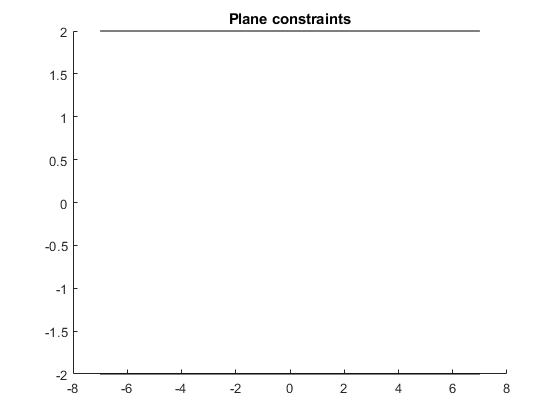

figure(1);
plot(pi_top, 'plane', 14);
hold on
plot(pi_bottom, 'plane', 14);
title('Plane constraints')

To prevent the collision between the robot and those walls, one strategy is to create one point-to-plane constraint for each of the robot's joints with respect to those planes. This corresponds to a total of fourteen linear constraints. 

Using DQ Robotics, they can be implemented as follows.

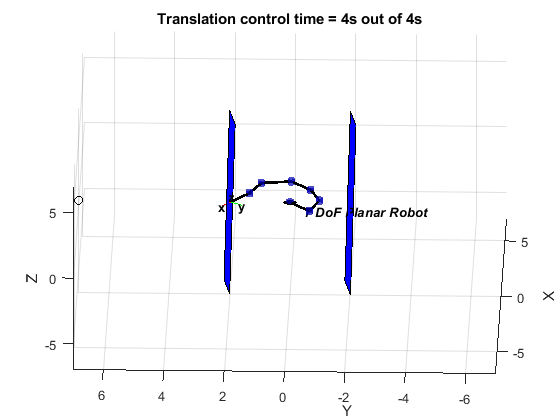

% Define a list of planes
plane_list = {pi_top, pi_bottom};

% Define the robot
seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

% Solver definition
qp_solver = DQ_QuadprogSolver();

% Controller definition
translation_controller = DQ_ClassicQPController(seven_dof_planar_robot, qp_solver);
translation_controller.set_control_objective(ControlObjective.Translation);
translation_controller.set_gain(10);
translation_controller.set_damping(1);

% VFI gain
eta_d = 1;

% Desired translation (pure quaternion)
td = 7*j_;
% Sampling time [s]
tau = 0.01;
% Simulation time [s]
final_time = 4;
% Initial joint values [rad]
q = 0.01*ones(7,1);

% Create a new figure
figure(2)
% Translation controller loop.
for time=0:tau:final_time
    
    % The inequality matrix and vector
    W = [];
    w = [];
    n = seven_dof_planar_robot.get_dim_configuration_space;
    for joint_counter=1:n
        
        % Get the pose Jacobian and pose of the current joint
        Jx = seven_dof_planar_robot.pose_jacobian(q, joint_counter);
        x = seven_dof_planar_robot.fkm(q, joint_counter);
        
        % Get the translation Jacobian and the translation of the current
        % joint
        Jt = DQ_Kinematics.translation_jacobian(Jx, x);
        t = translation(x);
        
        for plane_counter=1:length(plane_list)
            
            % Get the current plane
            workspace_plane = plane_list{plane_counter};
            
            % Calculate the point to plane distance Jacobian
            % We have to augment the Jp_pi with zeros
            Jp_pi = [DQ_Kinematics.point_to_plane_distance_jacobian(Jt, t, workspace_plane) zeros(1, n-joint_counter)];
            
            % Calculate the point to plane distance
            dp_pi = DQ_Geometry.point_to_plane_distance(t, workspace_plane);
            
            % Wq <= w
            W = [W; -Jp_pi];
            w = [w; eta_d*dp_pi];
        end
        
    end
    
    % Update the linear inequalities in the controller
    translation_controller.set_inequality_constraint(W, w);
    
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
    
    % Move the robot
    q = q + u*tau;
    
    % Plot
    % Plot the robot
    plot(seven_dof_planar_robot,q);
    title(['Translation control' ' time = ' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot3(td.q(2),td.q(3),td.q(4), 'ko');
    % Plot the walls
    plot(pi_top, 'plane', 14);
    plot(pi_bottom, 'plane', 14);
    hold off
    % [For animations only]
    drawnow limitrate % [For animations only] Ask MATLAB to draw the plot now
end

### Entry-sphere constraint

% Let us isolate the code of this section from the other sections
clear all;
close all;
include_namespace_dq;

A very common type of constraint in minimally invasive surgery is the entry-sphere constraint. Suppose there is an incision in the skin of the patient, positioned at

p = 5*j_;

Let us define the sphere to have a radius of 0.25 m. That is, we choose

d_safe = 0.25;

Moreover, let us attach to our planar robot a 2-meter-long shaft whose axis is collinear with the $x-$axis of the last link, as follows

% Define the initial joint configurations [rad]
q = (pi/8)*ones(7,1);

% Define the robot
seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

% Add the shaft
seven_dof_planar_robot.set_effector(1 + 0.5*E_*(2*i_));

Let us control the robot to the following desired translation

% Desired translation
td = -1*i_ + 4*j_;

In a way that the shaft never goes outside of the entry-sphere. Using DQ Robotics, this can be done as follows

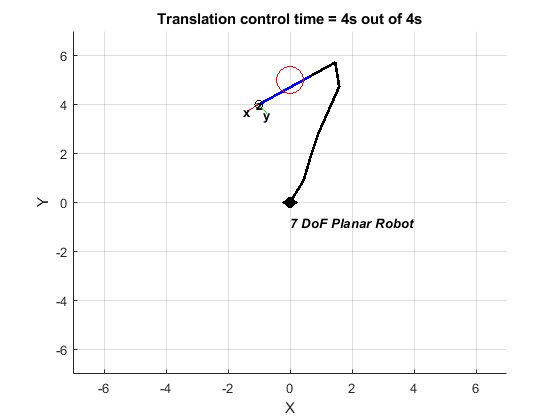

% Solver definition
qp_solver = DQ_QuadprogSolver();

% Controller definition
translation_controller = DQ_ClassicQPController(seven_dof_planar_robot, qp_solver);
translation_controller.set_control_objective(ControlObjective.Translation);
translation_controller.set_gain(10);
translation_controller.set_damping(1);

% VFI gain
eta_d = 1;

% Sampling time [s]
tau = 0.01;
% Simulation time [s]
final_time = 4;

% Create a new figure
f = figure(1);
% Translation controller loop.
for time=0:tau:final_time
    
    % Get the pose Jacobian and the pose
    Jx = seven_dof_planar_robot.pose_jacobian(q);
    x = seven_dof_planar_robot.fkm(q);
    
    % Get the line Jacobian for the x-axis
    Jl = DQ_Kinematics.line_jacobian(Jx, x, i_);
    
    % Get the line with respect to the base
    t = translation(x);
    r = rotation(x);
    l = Ad(r, i_);
    l_dq = l + E_*cross(t, l);
    
    % Get the line-to-point distance Jacobian
    Jl_p = DQ_Kinematics.line_to_point_distance_jacobian(Jl, l_dq, p);
    
    % Get the line-to-point square distance
    Dl_p = DQ_Geometry.point_to_line_squared_distance(p, l_dq);
    
    % Get the distance error
    D_safe = d_safe^2;
    D_tilde = D_safe - Dl_p;
    
    % The inequality matrix and vector
    W = Jl_p;
    w = eta_d*D_tilde;
    
    % Update the linear inequalities in the controller
    translation_controller.set_inequality_constraint(W, w);
    
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
    
    % Move the robot
    q = q + u*tau;
    
    % Clear plot
    plot(seven_dof_planar_robot, q)
    clf(f)
    % Plot the robot
    plot(seven_dof_planar_robot, q)
    title(['Translation control' ' time = ' num2str(time) 's out of ' num2str(final_time) 's'])
    hold on
    % Plot the desired pose
    hold on
    plot3(td.q(2),td.q(3),td.q(4), 'ko');
    % Plot the shaft in blue
    t_1 = translation(seven_dof_planar_robot.raw_fkm(q));
    t_2 = translation(seven_dof_planar_robot.fkm(q));
    plot3([t_1.q(2) t_2.q(2)],[t_1.q(3) t_2.q(3)],[t_1.q(4) t_2.q(4)],'b','LineWidth',2)
    % Plot the entry sphere
    plot3(p.q(2), p.q(3), p.q(4), 'ro', 'MarkerSize', 20)
    % [For animations only]
    drawnow limitrate % [For animations only] Ask MATLAB to draw the plot now
end

# Homework

Create a class called "VS050RobotDH" that represents the Denso VS050 robot, whose DH parameters are described in the following table. (remember lesson 6)

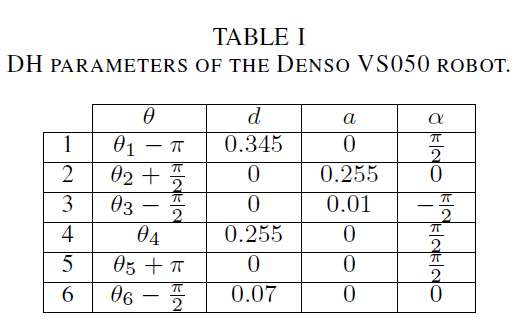

**End-effector:  **attach to the robot a 20cm-long-shaft along the $z-$axis of the last joint.

**Initial configuration: **${\it \bf q}(0) = \left[\matrix{0 & \frac{\pi}{3} & \frac{\pi}{3} & 0 & \frac{\pi}{3} & 0} \right]^T.$

1) Create a file called [vs050_plane_constraints.m] and do the following:

- Create a translation controller with $\tau=0.01$. Choose the other controller parameters so that the control is smooth (see this and prior lessons for examples).

- Create 6 planes centered around the point ${\it \bf p}_1=0.45\hat{\imath} + 0.08\hat{k}$, so that all normals are pointed inwards, to make a 5cm cube. (remember lesson 4)

- During control, use point-to-plane VFIs to keep the tooltip always inside the cubic region.

- Move the end-effector, in order, to the following four desired positions ${\it \bf t}_d=\left\{ 0.60\hat{\imath} + 0.08\hat{k}, 0.20\hat{\imath} + 0.15\hat{k}, 0.45\hat{\imath} + 0.08\hat{k}, 0.45\hat{\imath} + 0.0\hat{k}  \right\}$, for 4 simulation-time seconds each.

- Plot the task error in one figure

- Plot the distance of the end-effector to all the six planes using subplots in another figure.

2) Create a file called [vs050_entry_sphere_constraint.m] and do the following:

- Create a translation controller with $\tau=0.01$. Choose the other controller parameters so that the control is smooth (see this and prior lessons for examples).

- Consider the entry-sphere to be centered at ${\it \bf p}_2=0.45\hat{\imath}+0.2\hat{k}$. Consider the entry sphere to have a radius of 5 mm.

- During control, use a line-to-point VFI to keep the shaft always inside the entry-sphere.

- Move the end-effector, in order, to the following four desired positions ${\it \bf t}_d=
\left\{  
0.45\hat{\imath} + 0.03\hat{k},
0.48\hat{\imath} + 0.03\hat{k},
0.41\hat{\imath} + 0.03\hat{k},
0.40\hat{\imath} + 0.01\hat{k}
\right\}$, for 4 simulation-time seconds each.

- Plot the task error in one figure

- Plot the distance of the shaft to the center of the entry-sphere in another figure.